# IGVC SP23 Lane Detection Camera Transform

Diego Colón, Max DeSantis, Brenden Wickman

## Experimental Setup

A grid was overlaid on the image, and used to draw a tape grid in front of the camera. Yellow markers placed at each intersection were measured relative to camera position.

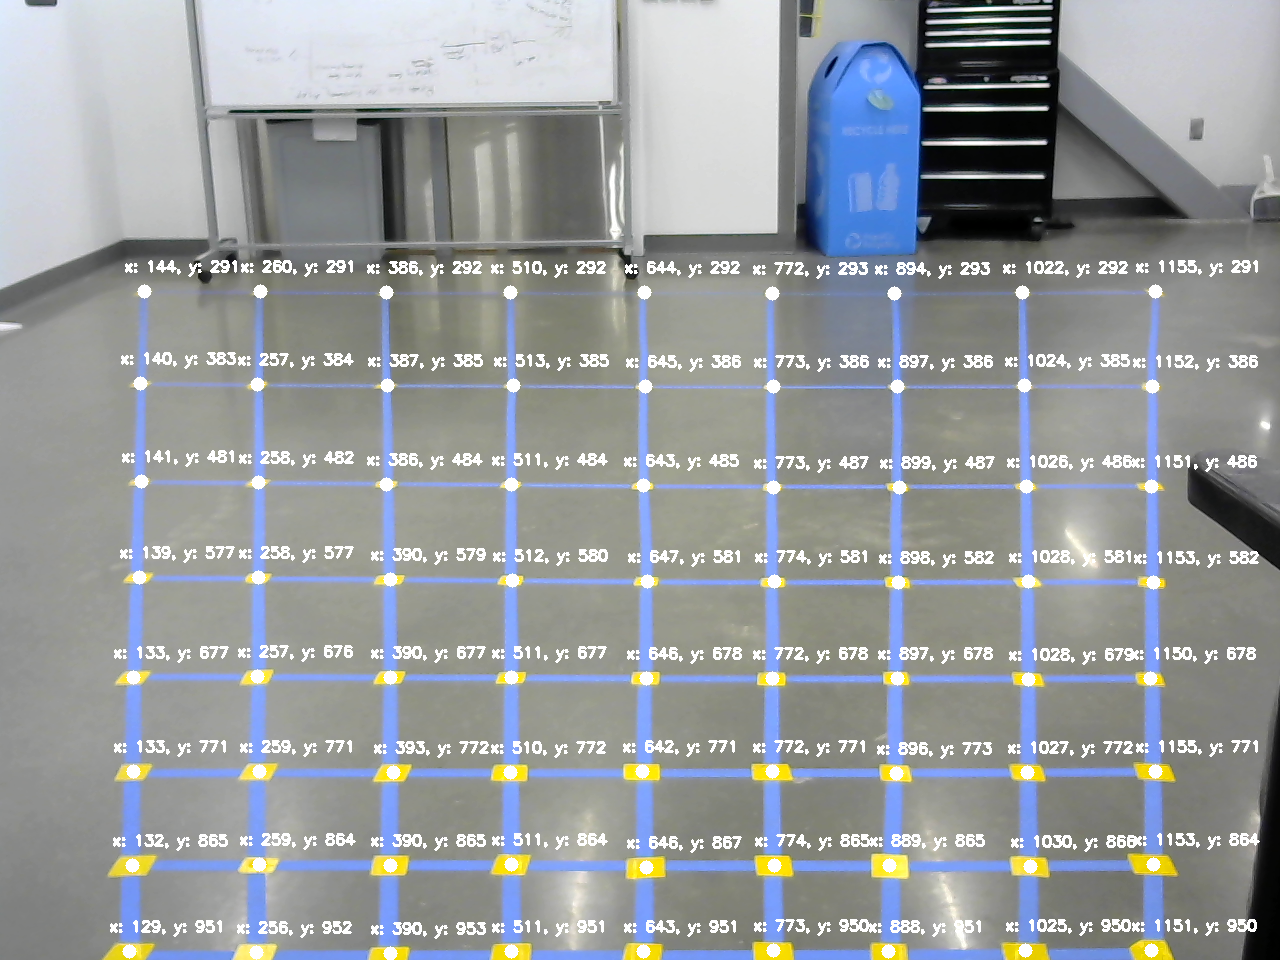

## Data Analysis

syms u v x y

imgData = importdata("positions.csv", ",");

static_u = 643;
static_v = 951;
static_x = 58;
static_y = 0;

u_data = imgData.data(:, 1) - static_u;
v_data = imgData.data(:, 2) - static_v; 
x_data = imgData.data(:, 3) + static_x;
y_data = imgData.data(:, 4) + static_y;

u_test = (min(u_data):10:max(u_data)).';
v_test = (min(v_data):10:max(v_data)).';

[u_data_mesh, v_data_mesh] = meshgrid(u_data,v_data);

### Plot input and output spaces

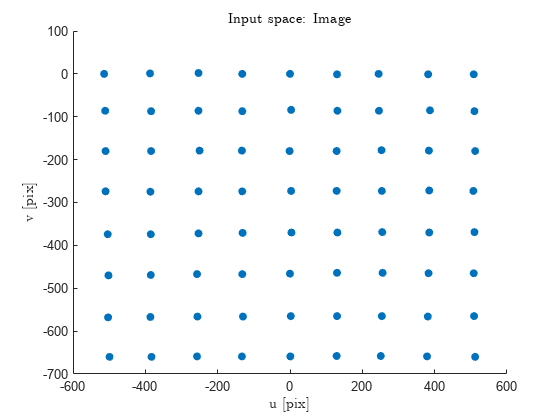

figure()
scatter(u_data,v_data,'filled')
xlabel("u [pix]",'Interpreter',"latex"), ylabel("v [pix]",'Interpreter',"latex")
title("Input space: Image",'Interpreter',"latex")

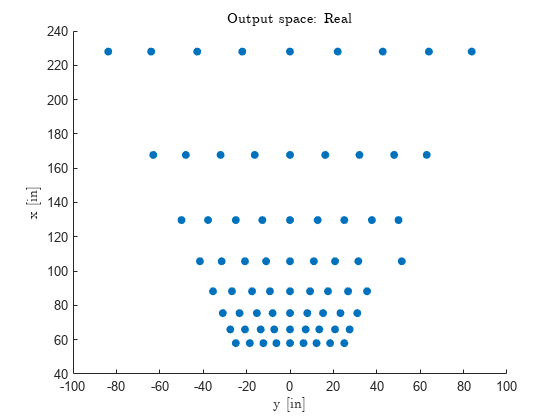

figure()
scatter(y_data,x_data,'filled')
xlabel("y [in]",'Interpreter',"latex"), ylabel("x [in]",'Interpreter',"latex")
title("Output space: Real",'Interpreter',"latex")

### Curve Fitting

#### 
$$f_1 :v\to x$$


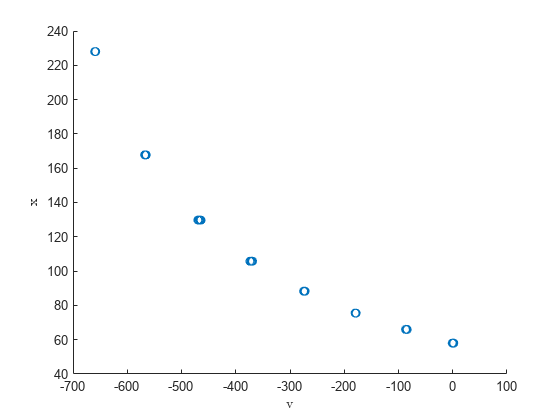

figure()
scatter(v_data,x_data)
xlabel("v",'Interpreter',"latex"); ylabel("x",'Interpreter',"latex")

[f1_fit, f1_gof] = fit(v_data,x_data,'exp2')

f1_fit =      General model Exp2:
     f1_fit(x) = a*exp(b*x) + c*exp(d*x)
     Coefficients (with 95% confidence bounds):
       a =      0.6725  (0.5309, 0.8142)
       b =   -0.007369  (-0.007632, -0.007107)
       c =       57.31  (57.13, 57.5)
       d =    -0.00137  (-0.001408, -0.001332)

f1_gof = struct with fields:
           sse: 13.4123
       rsquare: 0.9999
           dfe: 68
    adjrsquare: 0.9999
          rmse: 0.4441


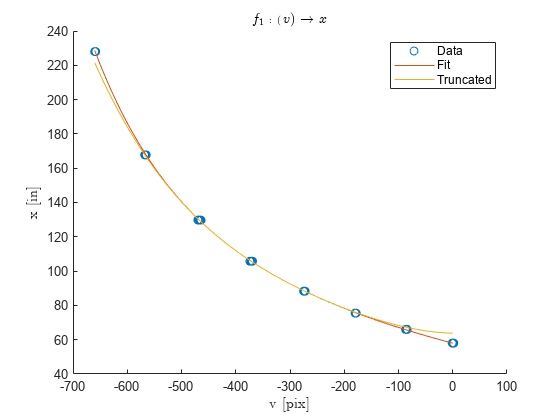

f1 = f1_fit.a*exp(f1_fit.b*v) + f1_fit.c*exp(f1_fit.d*v) ;
f1_trunc = taylor(f1,v,'ExpansionPoint',-350,'Order',5);
f1_trunc_val = matlabFunction(f1_trunc);

figure()
    hold on
        scatter(v_data,x_data,"DisplayName","Data")
        plot(v_test,f1_fit(v_test),"DisplayName","Fit")
        plot(v_test,f1_trunc_val(v_test),'DisplayName','Truncated')
    hold off
    legend()
    title("$f_1: (v) \to x$",'Interpreter','latex')
    xlabel("v [pix]",'Interpreter',"latex"); ylabel("x [in]",'Interpreter',"latex")

#### 
$$f_2 :\left(u,v\right)\to y$$


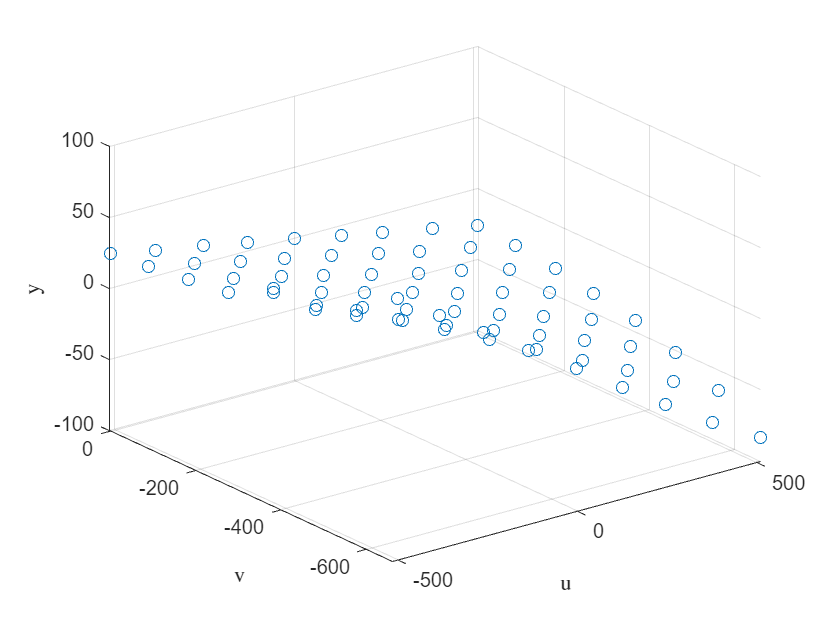

scatter3(u_data,v_data,y_data)
xlabel("u",'Interpreter',"latex"); ylabel("v",'Interpreter',"latex"); zlabel("y",'Interpreter',"latex")

[f2_fit, f2_gof] = fit([u_data,v_data],y_data,'poly13')

     Linear model Poly13:
     f2_fit(x,y) = p00 + p10*x + p01*y + p11*x*y + p02*y^2 + p12*x*y^2 + p03*y^3
     Coefficients (with 95% confidence bounds):
       p00 =     -0.1844  (-1.31, 0.9416)
       p10 =    -0.05183  (-0.05486, -0.0488)
       p01 =   -0.001935  (-0.01813, 0.01426)
       p11 =  -1.622e-05  (-3.802e-05, 5.574e-06)
       p02 =  -1.063e-07  (-5.997e-05, 5.976e-05)
       p12 =  -2.753e-07  (-3.072e-07, -2.435e-07)
       p03 =   4.218e-09  (-5.541e-08, 6.385e-08)



f2_gof = struct with fields:
           sse: 212.6484
       rsquare: 0.9971
           dfe: 65
    adjrsquare: 0.9968
          rmse: 1.8087


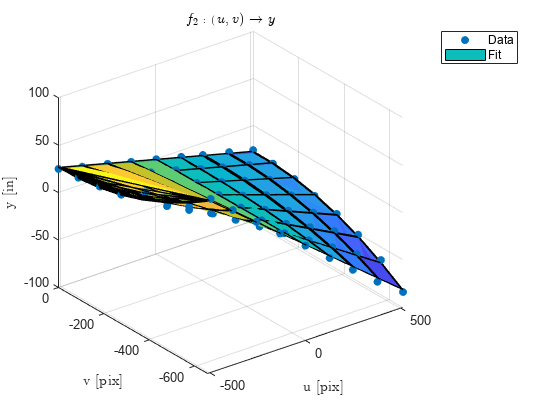

f2 = @(x,y) f2_fit.p00 + f2_fit.p10.*x + f2_fit.p01.*y + f2_fit.p11.*x.*y + f2_fit.p02.*y.^2 + f2_fit.p12.*x.*y.^2 +f2_fit.p03*y.^2;

figure()
    scatter3(u_data,v_data,y_data,'filled',"DisplayName","Data")
    hold on
        surface(u_data_mesh,v_data_mesh,f2(u_data_mesh,v_data_mesh),"DisplayName","Fit")
    hold off
    legend()
    title("$f_2: (u,v) \to y$",'Interpreter','latex')
    xlabel("u [pix]",'Interpreter',"latex"); ylabel("v [pix]",'Interpreter',"latex"); zlabel("y [in]",'Interpreter',"latex")